%Number 1; n = 20
result = 0;
input = 20;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result =     10


%Number 2; n = 100
result = 0;
input = 100;
for i = 1:input
    result = result + i*((-1)^i);
end
result

result =     50


%Number 2; long format
f = @(x) 0.5*(x-1)^2;
format long;

f(sqrt(3))

ans =    0.267949192431123


% 0.267949192431123

%Number 2; short format
format short;

f(sqrt(3))

ans = 0.2679

%0.2679

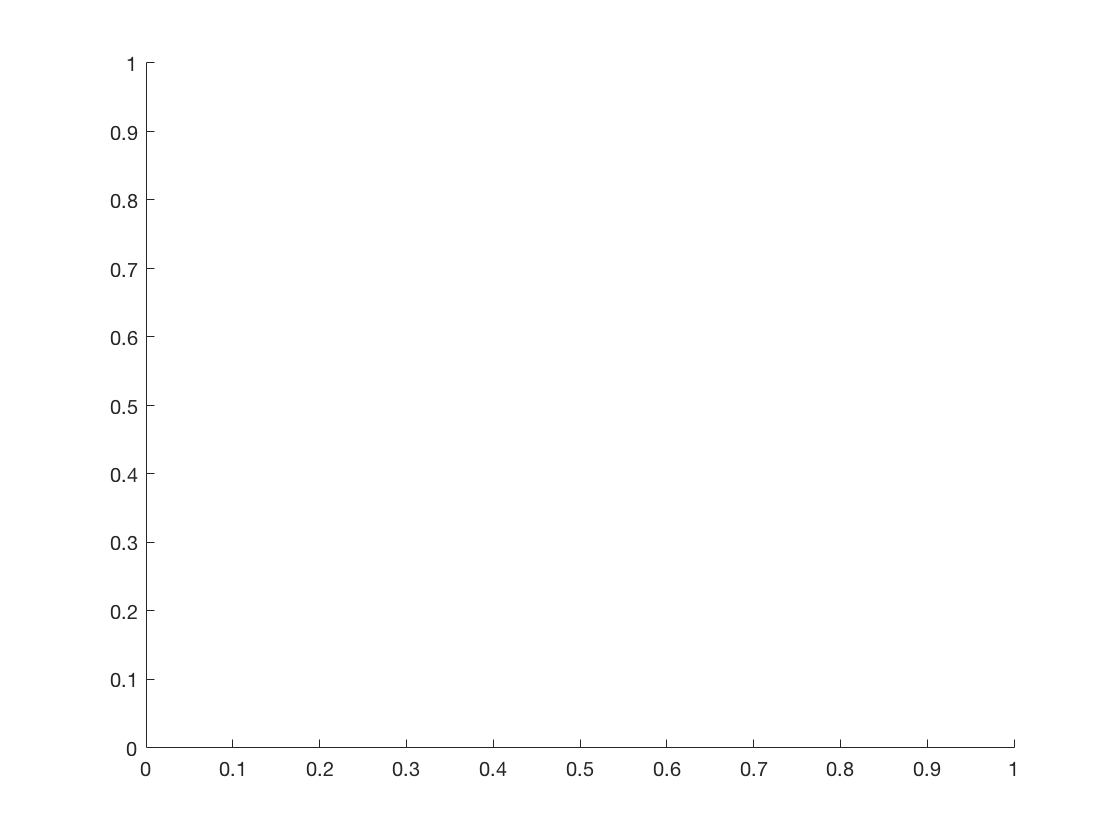

%Number 3 Plotting both functions on same graph
t = linspace(0,1,10);
t2 = linspace(0,1,100);
hold on

plot(t,f(t))

Error using  ^ 
Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To perform elementwise matrix powers, use '.^'.

Error in worksheet1>@(x)0.5*(x-1)^2

plot(t2,f(t2))
legend({'f(1:10)','f(1:100)'},'Location','northwest');
xlabel("X Axis");
ylabel("Y Axis");
hold off

%Number 4
h = @(x,h)(f(x+h)-f(x))/h;

h(1.1,0.1)
h(1.1,0.01)
h(1.1,0.001)

%Number 5
t = linspace(0,2,100);
% derivative = @(d) (d-1);
line = @(m,x) m*(x-1.1) + 0.005  

plot(t,f(t),t,line(.1,t),t,line(h(1.1,0.1),t))